%% Figure show(Only do on local computer)
load("3.15TriSU321_r5_SSF.mat")
figure
yyaxis left
for L=2:size(SSF123_Gamma,1)
    hold on
    plot(SSF123_Gamma(1,:),SSF123_Gamma(L,:)/9,"LineWidth",2);
    plot(SSF123_K(1,:),SSF123_K(L,:)/9,"LineWidth",2);
end
title("SSF, r=5","FontSize",20);
xlabel("\theta","FontSize",18);
ylabel("S_{su2}","FontSize",18)
xlim([0,1])

yyaxis right
for L=2:size(SSF8_Gamma,1)
    hold on
    plot(SSF8_Gamma(1,:),SSF8_Gamma(L,:)/9,"LineWidth",2);
    plot(SSF8_K(1,:),SSF8_K(L,:)/9,"LineWidth",2);
end
hold off
xlabel("\theta","FontSize",12);
ylabel("S_8","FontSize",12)
xline(0.035,"LineWidth",3,"LineStyle",":")
xline(0.58,"LineWidth",3,"LineStyle",":")
xline(0.825,"LineWidth",3,"LineStyle",":")
xline(0.93,"LineWidth",3,"LineStyle",":")
legend("S_{su2}(\Gamma)","S_{su2}(K)","S_{8}(\Gamma)","S_{8}(K)",'FontSize',18)
fig=gcf

fig =   Figure (2) - 属性:

      Number: 2
        Name: ''
       Color: [1 1 1]
    Position: [488 342 560 420]
       Units: 'pixels'

  显示 所有属性


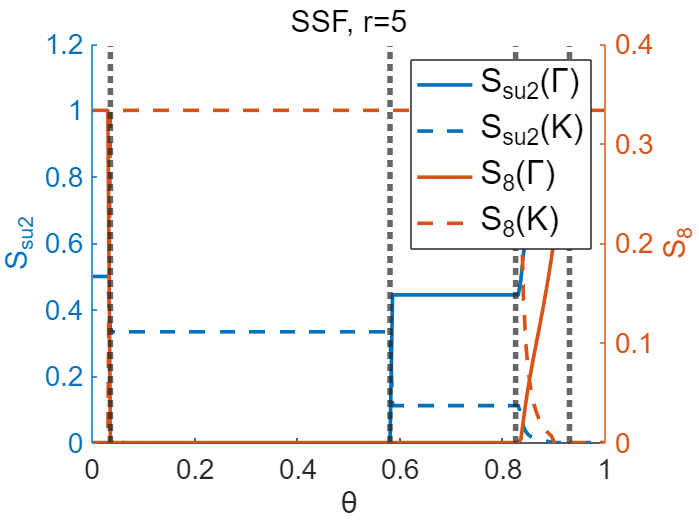

ax=findall(fig,"Type","Axes");
set(ax,"FontSize",15)

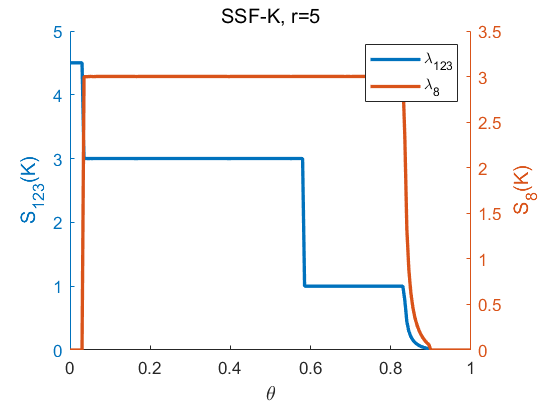



figure
yyaxis left
for L=2:size(SSF123_K,1)
    hold on
    plot(SSF123_K(1,:),SSF123_K(L,:),"LineWidth",2);
end
title("SSF-K, r=5","FontSize",12);
xlabel("\theta","FontSize",12);
ylabel("S_{123}(K)","FontSize",12)
xlim([0,1])

yyaxis right
for L=2:size(SSF8_K,1)
    hold on
    plot(SSF8_K(1,:),SSF8_K(L,:),"LineWidth",2);
end
legend("\lambda_{123}","\lambda_8")
xlabel("\theta","FontSize",12);
ylabel("S_8(K)","FontSize",12)